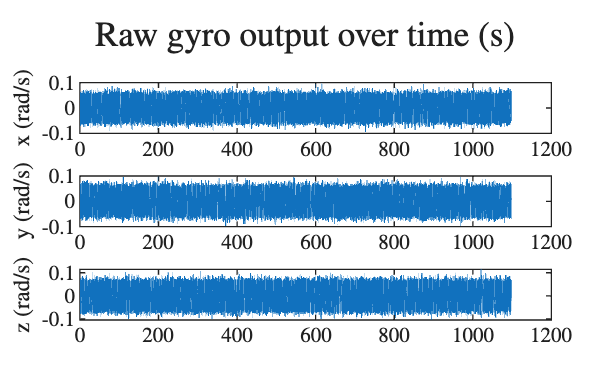

load('omegaGyroLog.mat')
figureWidth = 14; % cm (max. 15)
figureRatio = 0.6; % height to width ratio
set(groot, 'defaultTextInterpreter', 'latex')
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
RGB = rgb2hex(orderedcolors("gem"));

timestamp_gyro = (timestamp_gyro(5000:1085000-1) - timestamp_gyro(5000))/1000000;
gyrox = gyrox(5000:1085000-1) - mean(gyrox(5000:1085000-1));
gyroy = gyroy(5000:1085000-1) - mean(gyroy(5000:1085000-1));
gyroz = gyroz(5000:1085000-1) - mean(gyroz(5000:1085000-1));

figure(1), clf, hold on;
sgtitle("Raw gyro output over time (s)", "interpreter", "Latex")
subplot(3,1,1)
plot(timestamp_gyro, gyrox)
ylabel('x (rad/s)', "Interpreter", "Latex")
subplot(3,1,2)
plot(timestamp_gyro, gyroy)
ylabel('y (rad/s)', "Interpreter", "Latex")
subplot(3,1,3)
plot(timestamp_gyro, gyroz)
ylabel('z (rad/s)', "Interpreter", "Latex")
hold off

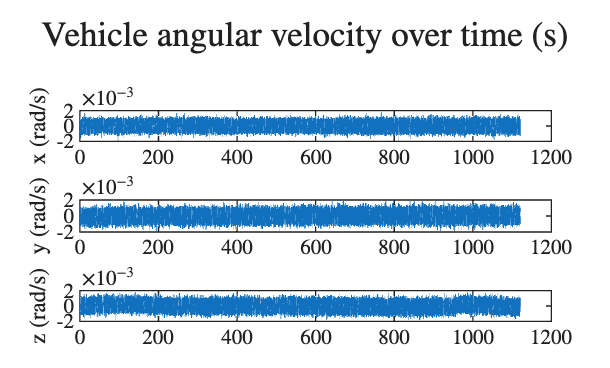


timestamp_omega = (timestamp_omega(5000:1085000-1) - timestamp_omega(5000))/1000000;
omegax = omegax(5000:1085000-1) - mean(omegax(5000:1085000-1));
omegay = omegay(5000:1085000-1) - mean(omegay(5000:1085000-1));
omegaz = omegaz(5000:1085000-1) - mean(omegaz(5000:1085000-1));

figure(2), clf, hold on;
sgtitle("Vehicle angular velocity over time (s)", "interpreter", "Latex")
subplot(3,1,1)
plot(timestamp_omega, omegax)
ylabel('x (rad/s)', "Interpreter", "Latex")
subplot(3,1,2)
plot(timestamp_omega, omegay)
ylabel('y (rad/s)', "Interpreter", "Latex")
subplot(3,1,3)
plot(timestamp_omega, omegaz)
ylabel('z (rad/s)', "Interpreter", "Latex")
hold off

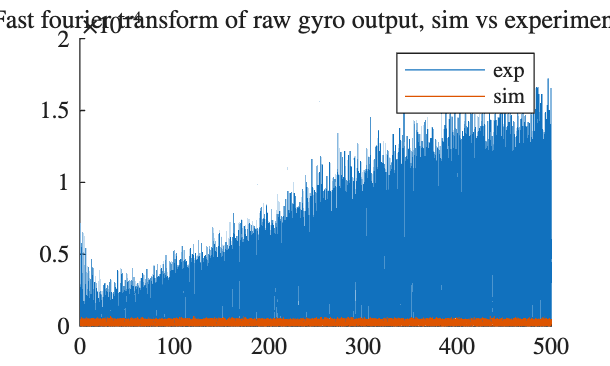

Fs = 1000; % Hz
L_exp = length(gyrox);
L_sim = length(out.simgyrox.signals.values);

gyrox_fft = abs(fft(gyrox)/L_exp);
gyrox_fft = gyrox_fft(1:L_exp/2+1);
gyrox_fft(2:end-1) = 2*gyrox_fft(2:end-1);

simgyrox_fft = abs(fft(out.simgyrox.signals.values)/L_sim);
simgyrox_fft = simgyrox_fft(1:L_sim/2+0.5);
simgyrox_fft(2:end-1) = 2*simgyrox_fft(2:end-1);

figure(3),clf, hold on;
plot(Fs/L_exp*(0:L_exp/2), gyrox_fft);
plot(Fs/L_sim*(0:L_sim/2), simgyrox_fft);
legend('exp','sim')
title("Fast fourier transform of raw gyro output, sim vs experimental", "Interpreter", "Latex")
hold off;

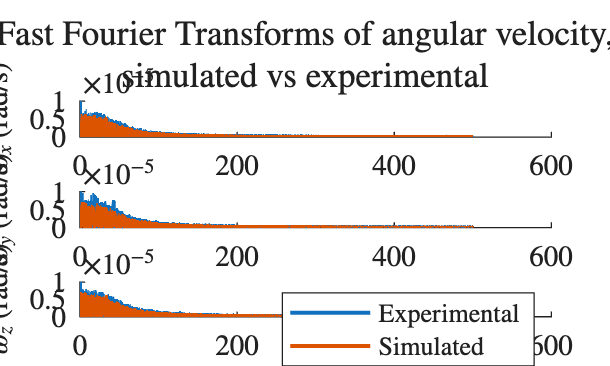



omegax_fft = abs(fft(omegax)/L_exp);
omegax_fft = omegax_fft(1:L_exp/2+1);
omegax_fft(2:end-1) = 2*omegax_fft(2:end-1);

simomegax_fft = abs(fft(out.simomegax.signals.values)/L_sim);
simomegax_fft = simomegax_fft(1:L_sim/2+0.5);
simomegax_fft(2:end-1) = 2*simomegax_fft(2:end-1);


omegay_fft = abs(fft(omegay)/L_exp);
omegay_fft = omegay_fft(1:L_exp/2+1);
omegay_fft(2:end-1) = 2*omegay_fft(2:end-1);

simomegay_fft = abs(fft(out.simomegay.signals.values)/L_sim);
simomegay_fft = simomegay_fft(1:L_sim/2+0.5);
simomegay_fft(2:end-1) = 2*simomegay_fft(2:end-1);


omegaz_fft = abs(fft(omegaz)/L_exp);
omegaz_fft = omegaz_fft(1:L_exp/2+1);
omegaz_fft(2:end-1) = 2*omegaz_fft(2:end-1);

simomegaz_fft = abs(fft(out.simomegaz.signals.values)/L_sim);
simomegaz_fft = simomegaz_fft(1:L_sim/2+0.5);
simomegaz_fft(2:end-1) = 2*simomegaz_fft(2:end-1);



figure(4),clf;
subplot(3,1,1), hold on;
plot(Fs/L_exp*(0:L_exp/2), omegax_fft);
plot(Fs/L_sim*(0:L_sim/2), simomegax_fft);
ylabel('$\omega_x$ (rad/s)', "Interpreter", "Latex")
ylim([0 1e-5])
hold off;
subplot(3,1,2), hold on;
plot(Fs/L_exp*(0:L_exp/2), omegay_fft);
plot(Fs/L_sim*(0:L_sim/2), simomegay_fft);
ylabel("$\omega_y$ (rad/s)", "Interpreter", "Latex")
ylim([0 1e-5])
hold off;
subplot(3,1,3), hold on;
plot(Fs/L_exp*(0:L_exp/2), omegaz_fft);
plot(Fs/L_sim*(0:L_sim/2), simomegaz_fft);
ylabel("$\omega_z$ (rad/s)", "Interpreter", "Latex")
ylim([0 1e-5])

xlabel('Frequency (Hz)')

set(findall(gcf, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])

hold off;
legend('Experimental','Simulated')
sgtitle({"Fast Fourier Transforms of angular velocity,", "simulated vs experimental"}, "Interpreter", "Latex")

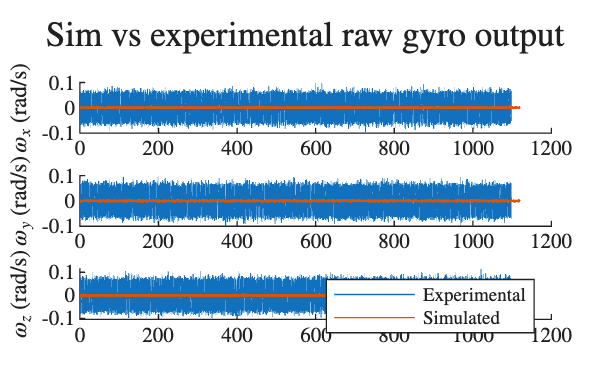

figure(5), clf;
subplot(3,1,1), hold on;
plot(timestamp_gyro,gyrox);
plot(out.simgyrox.time, out.simgyrox.signals.values);
hold off;
ylabel('$\omega_x$ (rad/s)', "Interpreter", "Latex")
subplot(3,1,2), hold on;
plot(timestamp_gyro,gyroy);
plot(out.simgyroy.time, out.simgyroy.signals.values);
hold off;
ylabel('$\omega_y$ (rad/s)', "Interpreter", "Latex")
subplot(3,1,3), hold on;
plot(timestamp_gyro,gyroz);
plot(out.simgyroz.time, out.simgyroz.signals.values);
ylabel('$\omega_z$ (rad/s)', "Interpreter", "Latex")
legend('Experimental', 'Simulated');
hold off;
sgtitle("Sim vs experimental raw gyro output", "Interpreter", "Latex")

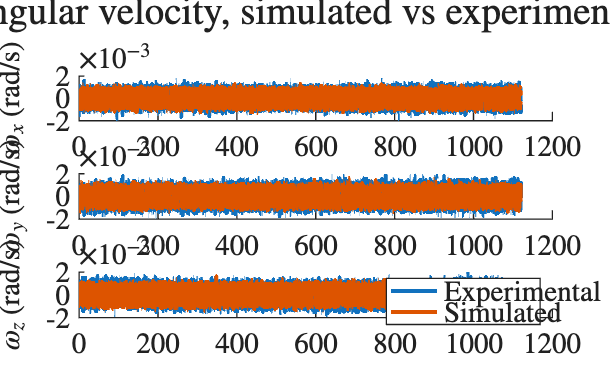



figure(6), clf;
subplot(3,1,1), hold on;
plot(timestamp_omega,omegax);
plot(out.simomegax.time, out.simomegax.signals.values);
hold off;
ylabel('$\omega_x$ (rad/s)', "Interpreter", "Latex")
subplot(3,1,2), hold on;
plot(timestamp_omega,omegay);
plot(out.simomegay.time, out.simomegay.signals.values);
hold off;
ylabel('$\omega_y$ (rad/s)', "Interpreter", "Latex")
subplot(3,1,3), hold on;
plot(timestamp_omega,omegaz);
plot(out.simomegaz.time, out.simomegaz.signals.values);
ylabel('$\omega_z$ (rad/s)', "Interpreter", "Latex")
legend('Experimental', 'Simulated');

xlabel('Time (s)')

set(findall(gcf, 'Type', 'Line'), 'LineWidth', 1.5);
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);
set(gcf,'Units','centimeters','Position',[3 3 figureWidth figureRatio*figureWidth])
set(gcf,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[figureWidth figureRatio*figureWidth])

hold off;
sgtitle({"Angular velocity, simulated vs experimental"}, "Interpreter", "Latex")